## Inintailization

clc; clear all; close all;

## Data reading

[data, datatxt,dataraw] = xlsread("test1_1.xlsx");
[m n] = size(data);

## Data Plotting & Visualization

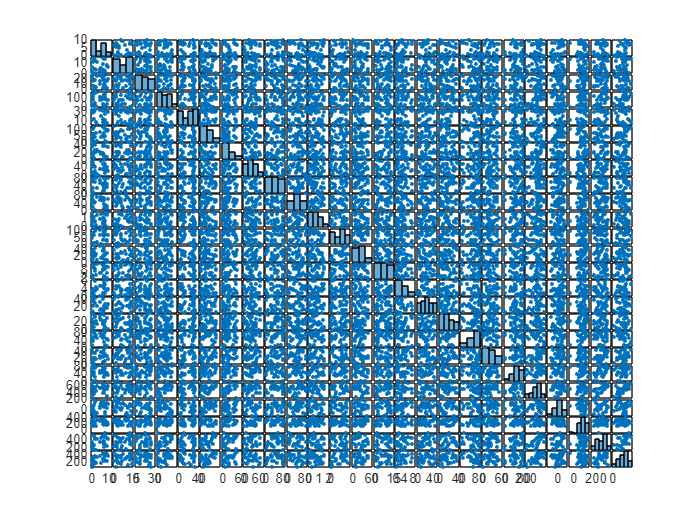

figure(1);
gplotmatrix(data);

% corrplot(data);

## Data Segmentation : Training set & Test set

maxValue = max(max(data));
data = data./maxValue;

[m n] = size(data);
trainingPortion = 0.8;
rIndex = randperm(m)';

trainIndex = floor(m.*trainingPortion);

trainingData = data(rIndex(1:trainIndex),:);
testData = data(rIndex(trainIndex+1:m),:);

trainingX = trainingData(:,1:20);
trainingY = trainingData(:,21:25);
testX = testData(:,1:20);
testY = testData(:,21:25);

## Deep neural network designer

layers = [
    featureInputLayer(20,"Name","featureinput")
    fullyConnectedLayer(30,"Name","fc")
    tanhLayer("Name","tanh")
    fullyConnectedLayer(25,"Name","fc_1")
    tanhLayer("Name","tanh_1")
    fullyConnectedLayer(15,"Name","fc_4")
    tanhLayer("Name","tanh_4")
    fullyConnectedLayer(10,"Name","fc_6")
    tanhLayer("Name","tanh_5")
    fullyConnectedLayer(8,"Name","fc_2")
    tanhLayer("Name","tanh_2")
    fullyConnectedLayer(7,"Name","fc_3")
    tanhLayer("Name","tanh_3")
    fullyConnectedLayer(5,"Name","fc_5")
    regressionLayer("Name","regressionoutput")];

%% 다이아몬드 형태로 펼쳤다가 줄여나감

## Deep learning Options

options = trainingOptions("adam", ...
    InitialLearnRate = 0.001, ...
    MaxEpoch = 2000, ...
    Plots = "training-progress");

## Deep Learning

단일 CPU에서 훈련합니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　ＲＭＳＥ　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０７　｜　　　　　　　　　１．１９　｜　　　　　　　　０．７　｜　　　０．００１０　｜
｜　　　　　　５０　｜　　　　　　５０　｜　　　　　００：００：０９　｜　　　　　　　　　０．３５　｜　　　　６．０ｅ－０２　｜　　　０．００１０　｜
｜　　　　　１００　｜　　　　　１００　｜　　　　　００：００：１０　｜　　　　　　　　　０．２８　｜　　　　４．０ｅ－０２　｜　　　０．００１０　｜
｜　　　　　１５０　｜　　　　　１５０　｜　　　　　００：００：１１　｜　　　　　　　　　０．２５　｜　　　　３．２ｅ－０２　｜　　　０．００１０　｜
｜　　　　　２００　｜　　　　　２００　｜　　　　　００：００：１２　｜　　　　　　　　　０．２３　｜　　　　２．７ｅ－０２　｜　　　０．００１０　｜
｜　　　　　２５０　｜　　　　　２５０　｜　　　　　００：００：１３　｜　　　　　　　　　０．２０　｜　　　　２．１ｅ－０２　｜　　　０．００１０　｜
｜　　　　　３００　｜　　　　　３００　｜　　　　　００：００：１４　｜　　　　　　　　　０．１８　｜　　　　１．７ｅ－０２　｜　　　０．００１０　｜
｜　　　　　３５０　｜　　　　　３５０　｜　　　　　００：００：１５　｜　　　　　　　　　０．１６　｜　　　　１．３ｅ－０２　｜　　　０．００１０　｜
｜　　　　　４００　｜　　　　　４００　｜　　　　　００：００：１６　｜　　　　　　　　　０．１４　｜　　　　９．７ｅ－０３　｜　　　０．００１

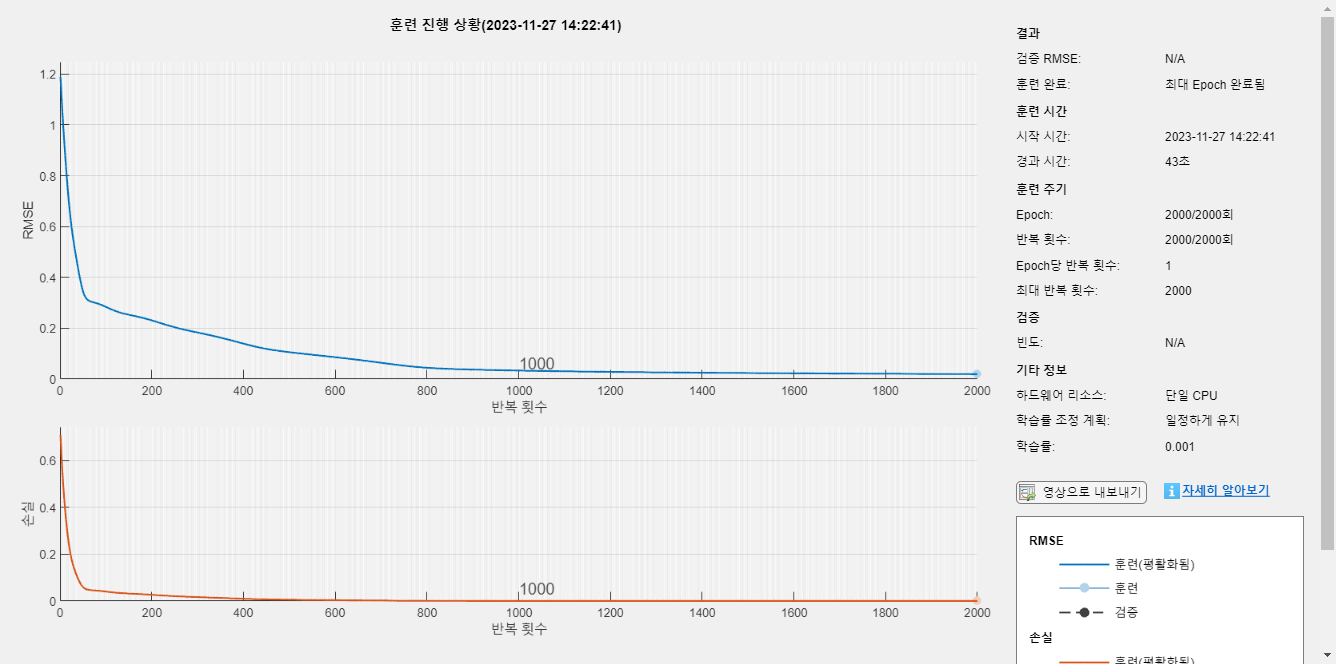

[net, info] = trainNetwork(trainingX,trainingY,layers,options);

## Deep Learning verfication & Test

yPredict = predict(net,testX);

yPredict = yPredict.*maxValue;

testY = testY.*maxValue;

## 7. Validation

예측값과 실제값의 차이에 대한 그래프

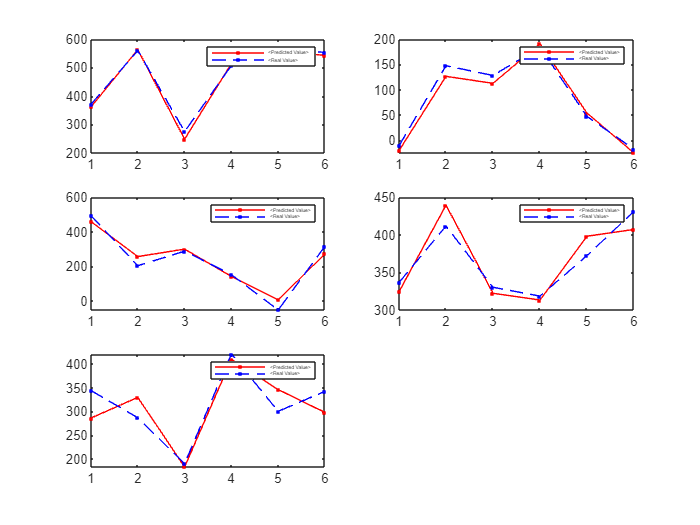

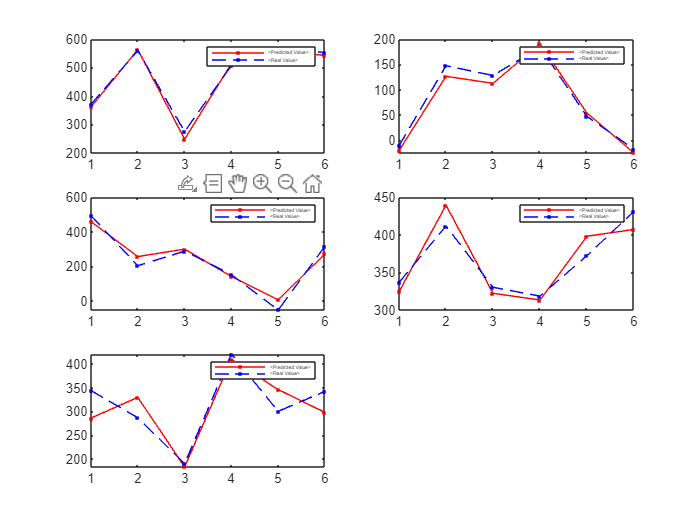

figure(1);
set(gcf,'color',[1 1 1]);

for i = 1:5
    subplot(3, 2, i); 
    plot(yPredict(:, i), 'r.-');
    hold on;
    plot(testY(:, i), 'b.--');
    hold off;

    legend('<Predicted Value>', '<Real Value>', 'Location', 'northeast', 'FontSize', 3);
end